**INSTITUTO POLITÉCNICO NACIONAL**

**UNIDAD PROFESIONAL INTERDISCIPLINARIA DE INGENIERÍA EN TECNOLOGÍAS AVANZADAS**

**Práctica 5:** Series de Fourier en tiempo continuo

**Materia:** Análisis de Señales y Sistemas

**Profesor:** Rafael Martínez Martínez

**Integrantes:**

Huerta Sánchez Jesus Alejandro.

Navarro Herrera Leon Ricardo.

Santos López Luis Enrique.

**GRUPO:** 2MV1

**Fecha de entrega:** 17/04/2020

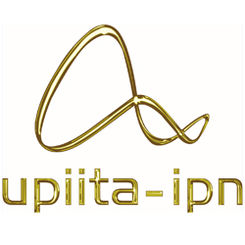                                                  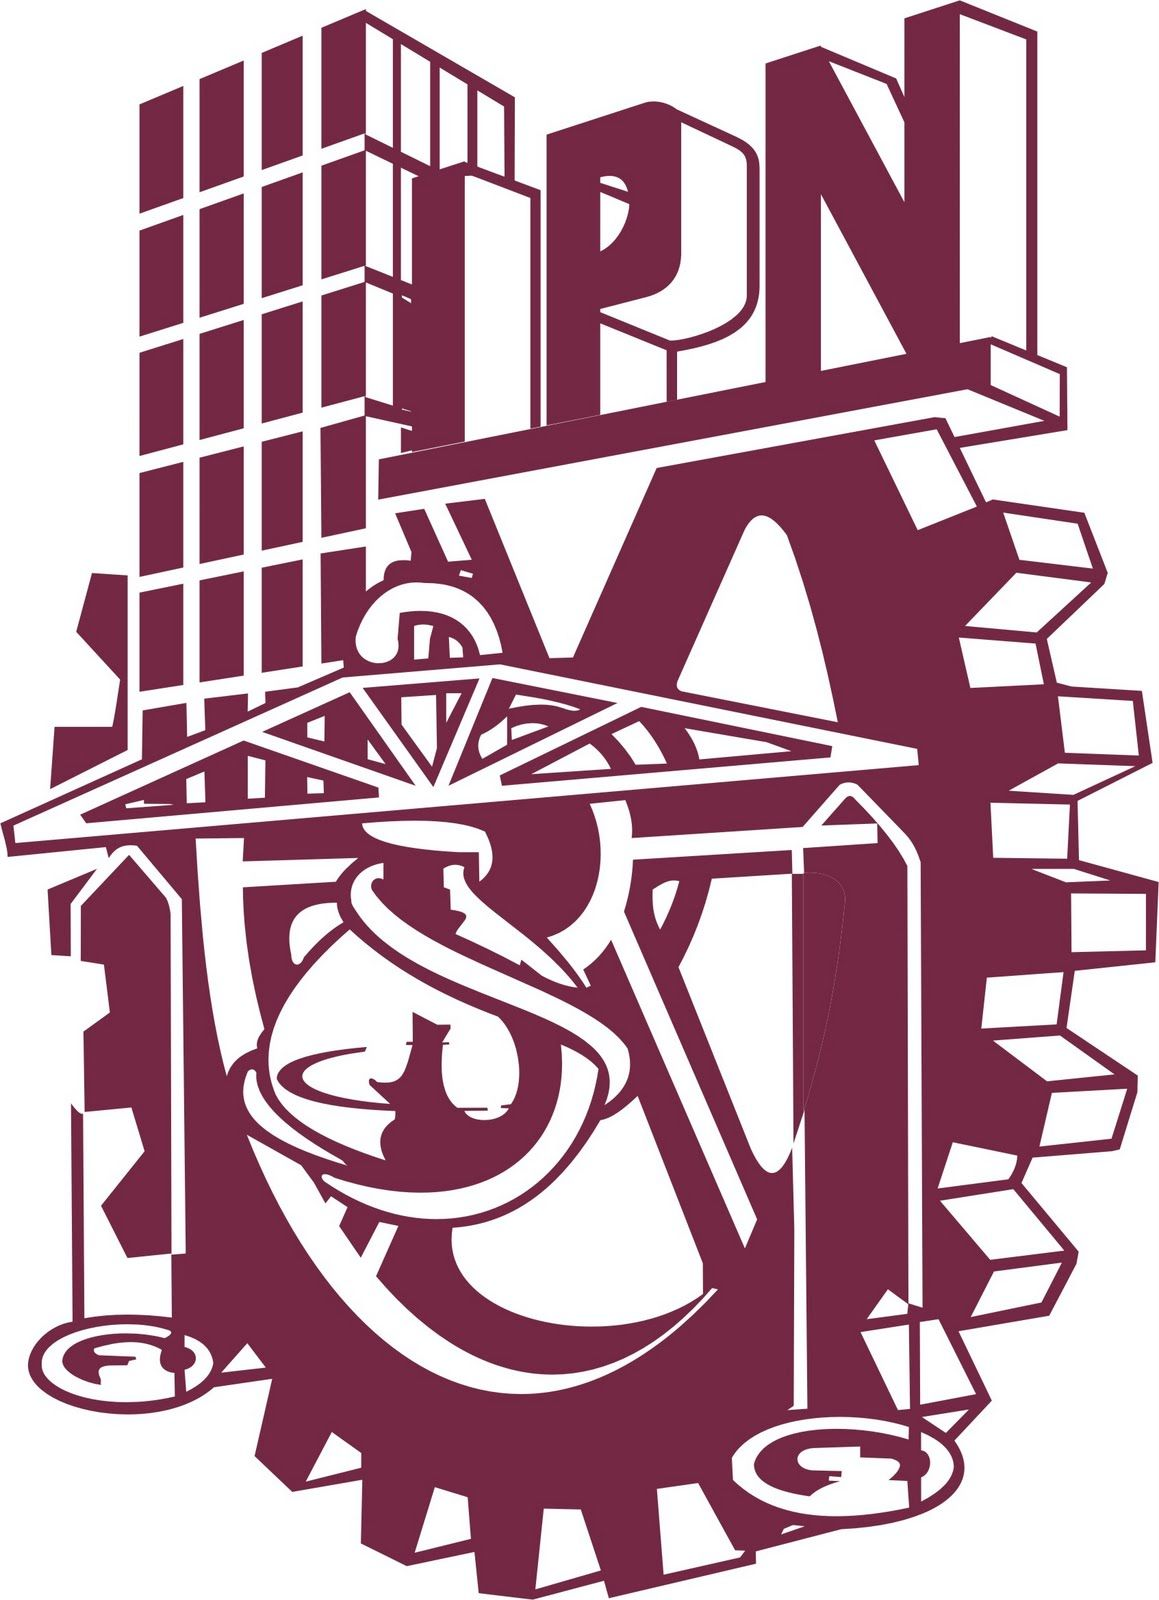

## Objetivos:

- Realizar gráficas de series de Fourier exponenciales y trigonométricas en tiempo continuo.

- Manipulación de instrucciones en MATLAB.

- Calculo númerico de los coeficientes de Fourier.

## Introducción:

**Aproximación númerica de los **$D_n$

Los  coeficientes de la serie de Fourier compleja $D_n$, estan dados por:


$$D_{n\;} =\frac{1}{T_0 }\int_{t_0 }^{t_0 +T_0 } x\left(t\right)e^{-j\;n\;\omega_0 \;t} \;\;\textrm{dt}$$


Hay varias razones para llevar a cabo esta integral por metodos numéricos, una de ellas es que la solución por metodos algebraicos sea muy complicada o extensa e incluso que no se puedan llevar a cabo. Existen una amplia gamma de algoritmos para aproximar numéricamente una integral, uno de ellos es mediante sumas de Riemann.


$$D_{n\;} =\frac{1}{T_0 }\int_{t_0 }^{t_0 +T_0 } x\left(t\right)e^{-j\;n\;\omega_0 \;t} \;\;\textrm{dt}=\underset{T\to 0}{\textrm{Lim}} \frac{1}{N_0 T}\sum_{k=0}^{N_0 -1} x\left(\textrm{kT}\right)e^{-j\;n\;\omega_{0\;} \textrm{kT}} \;T$$



$$=\underset{T\to 0}{\textrm{Lím}} \frac{1}{N_0 }\sum_{k=0}^{N_0 -1} x\left(\textrm{kT}\right)e^{-j\;n\;\omega_0 \;k\;T}$$


Donde 


$$N_0 =\frac{T_0 }{T}$$



$$\Omega_0 =\omega_0 T=\frac{2\pi }{N_0 }$$


Por lo que los $D_n$ se pueden aproximar mediante:


$$D_n =\frac{1}{N_0 }\sum_{k=0}^{N_0 -1} x\left(\textrm{kT}\right)e^{-j\;n\;\Omega_0 \;k}$$


Donde el límite se a ignorado devido a que no se puede obtener mediante un algoritmo múmerico, en lugar de esto tomaremos $N_0$ tan grande como nos sea posible.

## Desarrollo:

### Ejercicio 1

Ejemplo 6.1: Hallar la serie de Fourier Trigonometrica compacta para la función periodica mostrada en la figura: $x\left(t\right)=e^{-\frac{t}{2}}$    $0<t<\pi$  

**Solución:**

**Para 4 armónicos:**

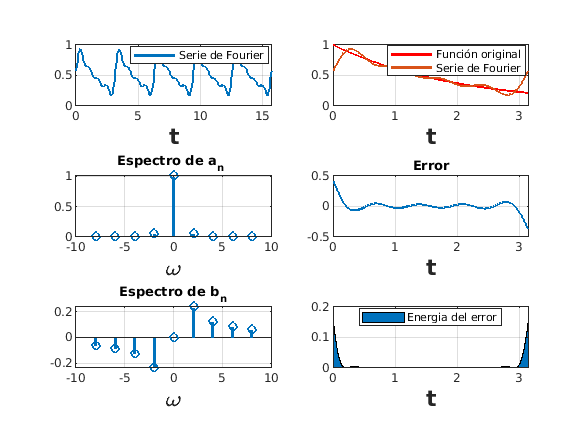

a0=0.504;
an=@(n) 0.504*2/(1+16*n^2);
bn=@(n) 0.504*8*n/(1+16*n^2);
t0=0;
tf=pi;
f=@(t) exp(-t/2);
armo=4;
a=0;
b=5*pi;
sfc1(t0,tf,an,bn,a0,f,armo,a,b)

**Para 15 armónicos:**

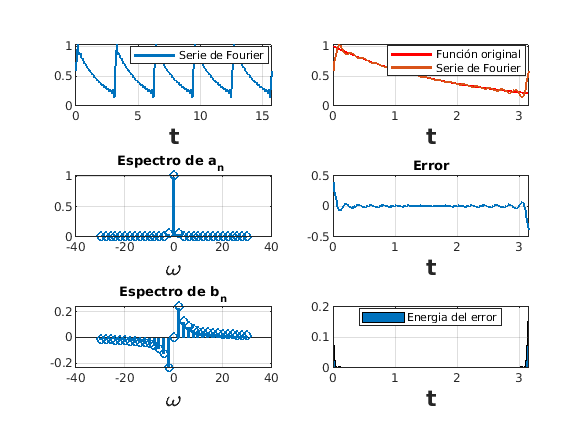

a0=0.504;
an=@(n) 0.504*2/(1+16*n^2);
bn=@(n) 0.504*8*n/(1+16*n^2);
t0=0;
tf=pi;
f=@(t) exp(-t/2);
armo=15;
a=0;
b=5*pi;
sfc1(t0,tf,an,bn,a0,f,armo,a,b)

### Ejercicio 2

Ejemplo 6.2: Hallar la serie de Fourier exponencial para la función periodica mostrada en la figura:$x\left(t\right)=-\left|6t-3\right|+3\;\;-0\ldotp 5\le t\le 1\ldotp 5$, tomando $A=3\ldotp$

Algunos Dn:

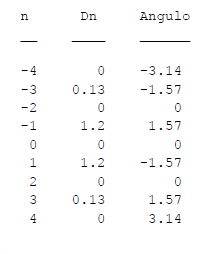

**Solución:**

**Para 4 armónicos:**

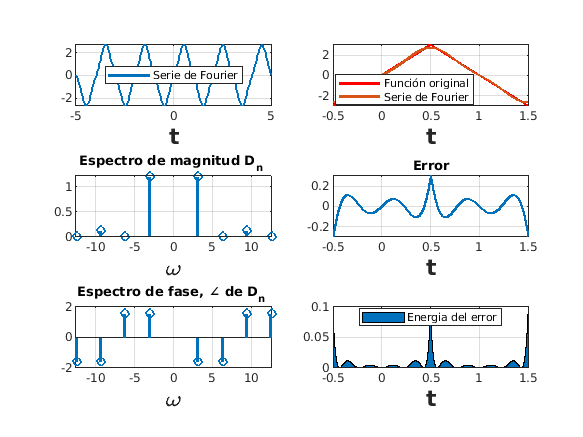

d0=0;
dn=@(n) -12*j*sin(n*pi/2)/(n^2*pi^2);
t0=-0.5;
tf=1.5;
f=@(t) -abs(6*t-3)+3;
armo=4;
a=-5;
b=5;
sfc(t0,tf,dn,d0,f,armo,a,b)

**Para 15 armónicos:**

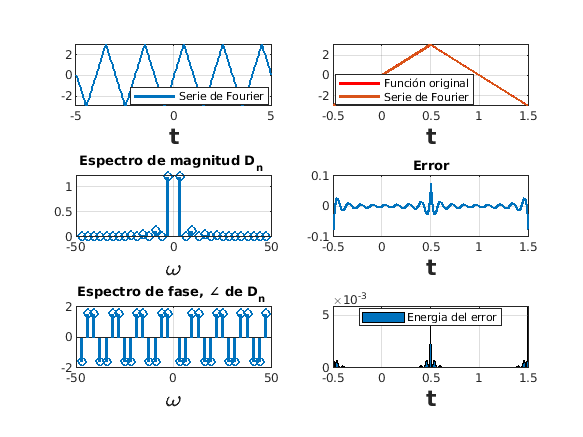

d0=0;
dn=@(n) -12*j*sin(n*pi/2)/(n^2*pi^2);
t0=-0.5;
tf=1.5;
f=@(t) -abs(6*t-3)+3;
armo=15;
a=-5;
b=5;
sfc(t0,tf,dn,d0,f,armo,a,b)

### Ejercicio 3

Ejemplo 6.4: Hallar la serie de Fourier para el pulso rectangular mostrado en la figura:

Algunos Dn:

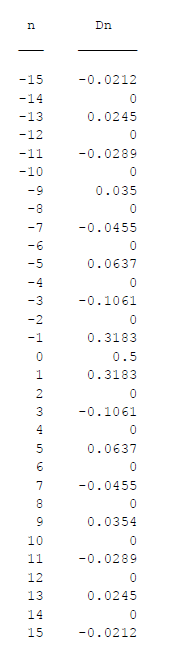

**Solución:**

**Para 4 armónicos:**

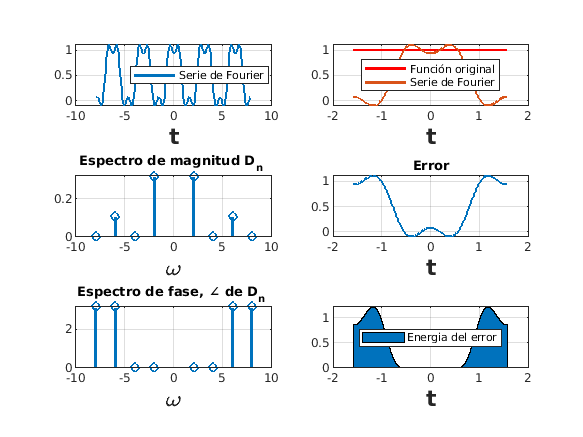

d0=1/2;
dn=@(n) 1/(n*pi)*sin(n*pi/2);
t0=-pi/2;
tf=pi/2;
f=@(t) rectpuls(t,pi);
armo=4;
a=-5*pi/2;
b=5*pi/2;
sfc(t0,tf,dn,d0,f,armo,a,b)

**Para 15 armónicos:**

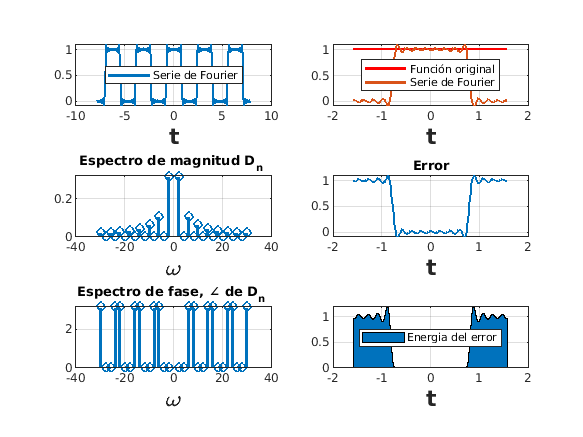

d0=1/2;
dn=@(n) 1/(n*pi)*sin(n*pi/2);
t0=-pi/2;
tf=pi/2;
f=@(t) rectpuls(t,pi);
armo=15;
a=-5*pi/2;
b=5*pi/2;
sfc(t0,tf,dn,d0,f,armo,a,b)

### Ejercicio 4

Hallar la serie de Fourier exponencial compleja para la funcion del Ejemplo 6.1

Solución:

**Para 4 armónicos:**

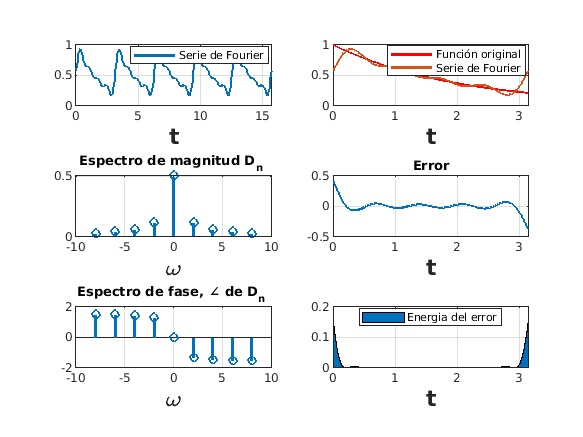

d0=0.504;
dn=@(n) 0.504/(1+4*n*j);
t0=0;
tf=pi;
f=@(t) exp(-t/2);
armo=4;
a=0;
b=5*pi;
sfc(t0,tf,dn,d0,f,armo,a,b)

**Para 15 armónicos:**

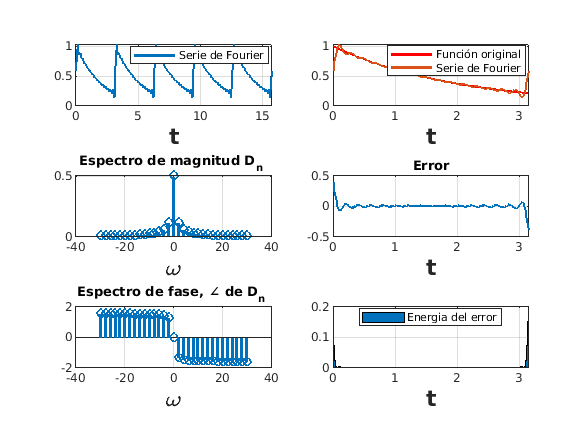

d0=0.504;
dn=@(n) 0.504/(1+4*n*j);
t0=0;
tf=pi;
f=@(t) exp(-t/2);
armo=15;
a=0;
b=5*pi;
sfc(t0,tf,dn,d0,f,armo,a,b)

### Ejercicio 5

Ejemplo 6.7: Hallar la serie y espectro exponencial y las gráficas solicitadas para $\delta_{\textrm{T0}} \left(t\right)\;$, con $T_0 =3$

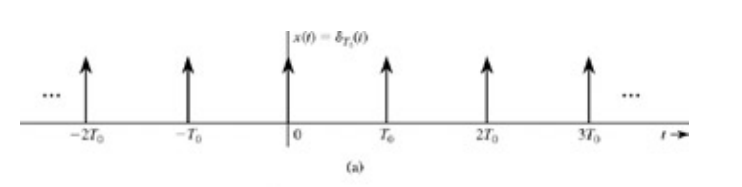

Se calculan los $D_n$


$$\omega_0 =\frac{2\pi }{3}$$



$$D_o =\frac{1}{3}$$



$$D_n =\frac{1}{3}$$



$$S_f \left(t\right)=\frac{1}{3}\left(\ldotp \ldotp \ldotp +{\;e}^{4\frac{\pi }{3}\;j\;t} +e^{2\frac{\pi }{3}j\;t} +1+e^{-2\frac{\pi }{3}\;j\;t} +e^{-4\frac{\pi }{3}\;j\;t\;\;} +\ldotp \ldotp \ldotp \right)$$


**Para 4 armónicos:**

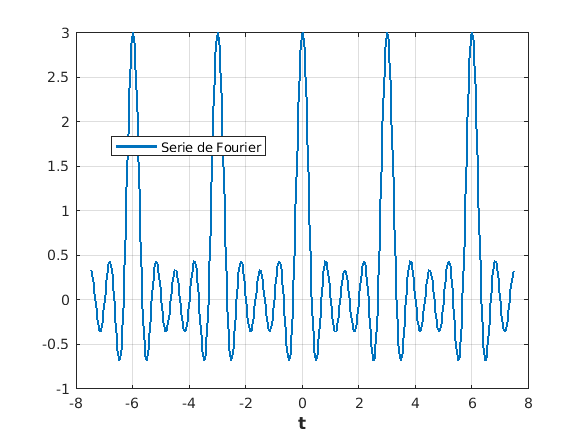

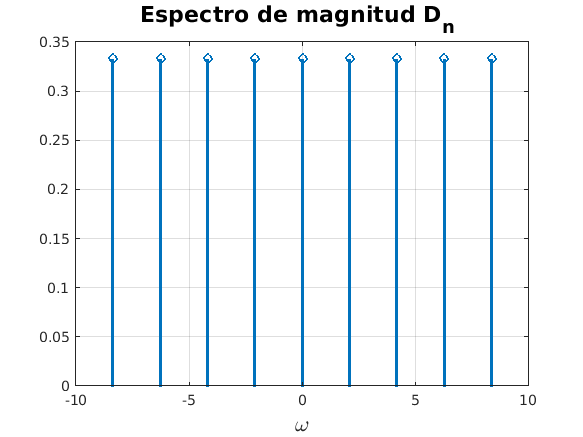

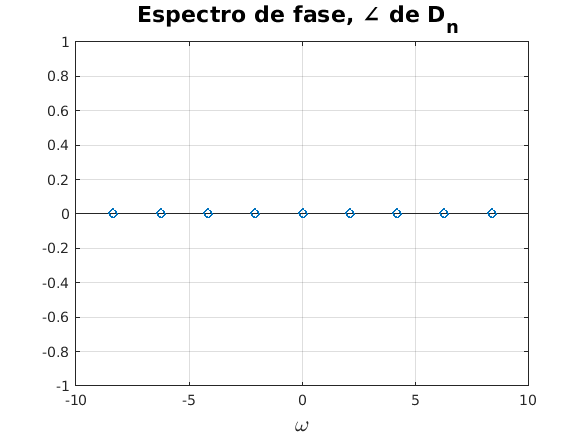

d0=1/3;
dn=@(n) 1/3;
t0=-1.5;
tf=1.5;
f=@(t) dirac(t);
armo=4;
a=-7.5;
b=7.5;
sfc2(t0,tf,dn,d0,f,armo,a,b)

**Para 15 armónicos:**

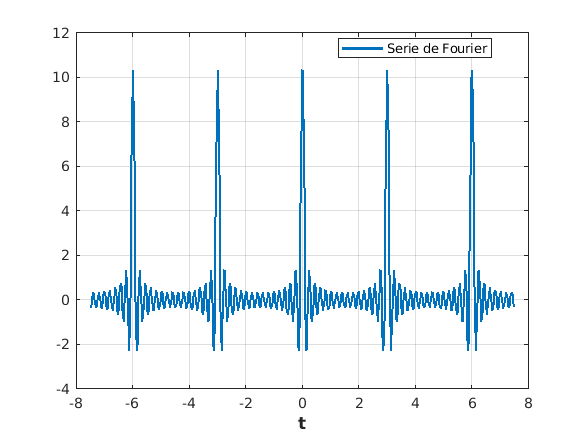

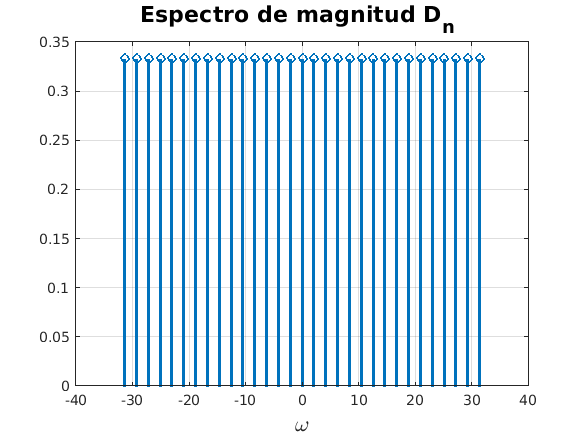

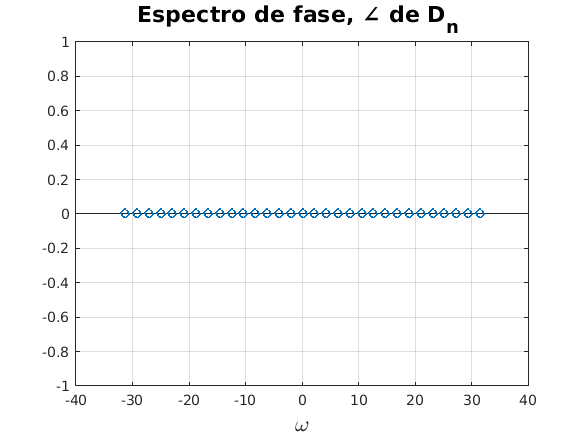

d0=1/3;
dn=@(n) 1/3;
t0=-1.5;
tf=1.5;
f=@(t) dirac(t);
armo=15;
a=-7.5;
b=7.5;
sfc2(t0,tf,dn,d0,f,armo,a,b)

### Ejercicio 6

Se elaboró un código similar al COMPUTER EXAMPLE C6.2 que se encuentra al final de la sección 6.2 de Lathi para el Ejemplo 6.2 con los datos indicados anteriormente (sin inline). 

$x\left(t\right)=-\left|6t-3\right|+3\;\;-0\ldotp 5\le t\le 1\ldotp 5$, tomando $A=3\ldotp$

Y obtenemos las gráficas siguientes con el código:

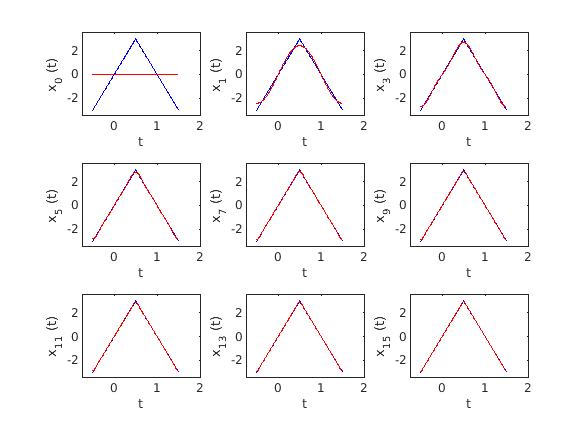

x=@(t) (6*t).*(t>=-0.5 & t<=0.5)+(6-6*t).*(t>0.5 & t<=1.5);
t = -0.5:0.01:1.5;
sumterms = zeros(16, length(t));
sumterms(1,:) = 0;
for n = 1:size(sumterms,1)-1;%filas  n son la n en la serie 
sumterms(n+1,:) = (24/(n.^2*pi.^2))*sin(n*pi*t)*sin((n*pi)/2);
end
xN = cumsum(sumterms);
figure(1); 
 clf; 
 ind = 0;
for N = [0,1:2:size(sumterms, 1)-1], %N es armonicos 
ind = ind+1;
 subplot (3,3,ind);
 plot(t,x(t),'b');
 hold on
 plot(t,xN(N+1,:),'r')
axis ([-0.75 2 -3.5 3.5]);
 xlabel ('t'); 
 ylabel (['x_{',num2str(N),'} (t)']);
end

### Ejercicio 7

Computer example C6.4: Para calcular los $D_0 \ldotp \ldotp \ldotp D_4$ del ejemplo de la práctica, se implemento el siguiente codigo en Matlab, utilizando el metodo del trapecio con $n=15$

a=0;
b=pi;
n=15

n = 15

h=(b-a)/n;
D=0;
    f=@(t) (exp(-t/2))/pi;
    
       for i=1:n
    D=D+(h/2)*(f(a)+f(a+h));
    a=a+h;
       end
D

D = 0.5047


f=@(t) (exp(-t/2)*exp(m*t*2*j))/pi;
for m=1:4
for i=1:n
    D=D+(h/2)*(f(a)+f(a+h));
    a=a+h;
end
D
end

D = 0.5053 + 0.0049i

D = 0.5054 + 0.0059i

D = 0.5054 + 0.0062i

D = 0.5054 + 0.0062i

Estos valores se calcularon nuevamente mediante el uso del codigo empleado en el ejemplo C6.4 de Lathi.

T_0 = pi;
 N_0 = 5; 
 T = T_0/N_0; 
 t = (0:T:T*(N_0-1))';
 M = 10; 
 x = exp(-t/2); 
 x(1) = (exp(-pi/2) + 1)/2;
  D_n = fft (x)/N_0

D_n =    0.5084 + 0.0000i
   0.0342 - 0.1017i
   0.0136 - 0.0250i
   0.0136 + 0.0250i
   0.0342 + 0.1017i


%   n = [-N_0/2:N_0/2-1]'; 
%   clf; subplot (2, 2, 1);
%   stem(n, abs(fftshift (D_n)),'k'); 
%   axis ([-M M -.1 .6]);
%   xlabel('n'); ylabel('|D_n|'); 
%   subplot (2, 2, 2); 
%   stem(n, angle(fftshift(D_n)),'k'); 
%   axis([-M M -pi pi]);
%   xlabel ('n');
%   ylabel('\angle D n [rad]');

Los resultados obtenidos en ambos codigos, asi como los calculados exactamente y sus respectivos errores se muestran la siguiente tabla.  

Para el cálculo analítico de los D_n tenemos la fórmula: $D_n =\frac{0\ldotp 504}{1+4\textrm{nj}}$

Y sabemos que $D_0 =0\ldotp 504$

Sustituyendo en la fórmula para los $D_1 ,\ldotp \ldotp \ldotp ,D_4$


$$D_1 =\frac{0\ldotp 504}{1+4\textrm{nj}}=\frac{0\ldotp 504}{1+4j}=0\ldotp 0296-0\ldotp 1185j$$



$$D_2 =\frac{0\ldotp 504}{1+4\textrm{nj}}=\frac{0\ldotp 504}{1+8j}=0\ldotp 0077-0\ldotp 0620j$$



$$D_3 =\frac{0\ldotp 504}{1+4\textrm{nj}}=\frac{0\ldotp 504}{1+12j}=0\ldotp 0034-0\ldotp 0417j$$



$$D_4 =\frac{0\ldotp 504}{1+4\textrm{nj}}=\frac{0\ldotp 504}{1+16j}=0\ldotp 0019-0\ldotp 0313j$$


Comparando los Dn calculados por los tres métodos nos queda:

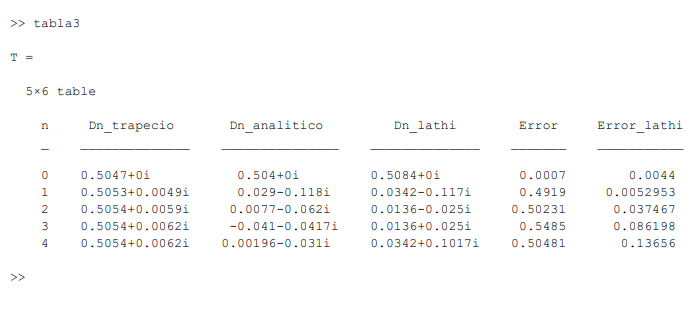

Donde podemos observar que el algoritmo propuesto por Lathi es mejor, ya que arroja valores mas cercanos a los exactos para el número seleccionado para n y su error es menor en general.

## Referencias Bibliograficas

- [https://www.zweigmedia.com/MundoReal/integral/numint.html](https://www.zweigmedia.com/MundoReal/integral/numint.html)

- [https://www.zweigmedia.com/MundoReal/integral/numint.html](https://www.zweigmedia.com/MundoReal/integral/numint.html)

- B. P. Lathi. (2005). Lineal systems and signals. New York: Oxford University Press 2da edición.